# Blackjack Optimal Performance Bound

As we are designing and/or learning policies to for the blackjack environment, it is helpful to have a sense of what is the "best" possible performance of a policy.

Recall that in the context of reinforcement learning a policy (decision-making rule) is a mapping from the current state ($s$) to an action ($a$).   An optimal policy is the best action to be taking in the current situation and can be expressed as

$a = \pi_*(s)$.

Also recall that in the blackjack environment the state of the system is fully observable (there is no sensing uncertainty) so the state is synonymous with the observations during each time step.   Each state/observation is `[player sum, dealer showing, useable ace]` and the resulting action is either `stick` or `hit`.

## Optimal Blackjack Policy

The [Barto and Sutton textbook](http://incompleteideas.net/book/the-book-2nd.html) provides a visual desciption of the optimal policy as....

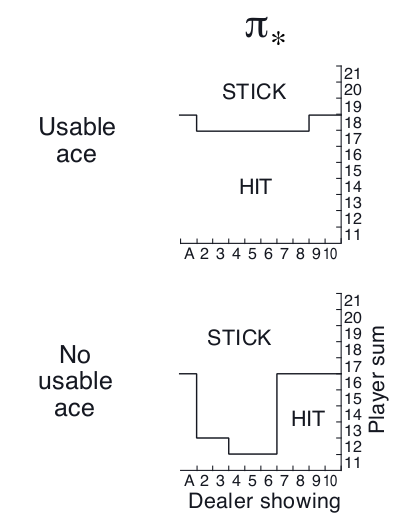

We can implement this policy as a function where the input is the state and the otuput is the action.

function action = policy_optimal(state)
    % Unpack the state
    player = state(1);
    dealer = state(2);
    ace = state(3);
    % Policy expressed as conditionals
    action = 2;  % hit as default
    if ace
        if ( (player >= 19) || ((player == 18) && ((dealer >= 2) && (dealer <= 8))) )
            action = 1;
        end
    else
        if ( (player >= 17) || ...
                ( (player >= 13) && ((dealer >= 2) && (dealer <= 6)) ) ||...
                ( (player == 12) && ((dealer >= 4) && (dealer <= 6)) ) )
            action = 1;
        end
    end
end

## Evaluate Performance

To evaluate the performance of the policy we can play N games and record the rewards for each episode.

N = 10000;
% Allocate storage 
rewards = zeros(1, N);
episode_length = zeros(1, N);
% Play N games
env = BlackJackEnv(1);
for ii = 1:N
    [obs, info] = env.reset();
    terminated = false;
     % Play one episode
    while ~terminated
        action = policy_optimal(obs);
        [obs, reward, terminated, truncated, info] = env.step(action);
    end
    rewards(ii) = reward;
    episode_length(ii) = info.episode_step;
end

## Mean Reward and Confidence Interval

We can easily estimate the mean expected reward for our optimal policy from the results of testing our policy with N episodes, but each time we run this evaluation the mean will be slighly different because of the uncertainty in the game.   Therefore, it is better to also estimate the confidence bounds for our estimtae of the mean.   The more trials we do, the tighter the confidence interval, the less randomness in our estimate of the true mean reward.

N = length(rewards);
mean_reward = mean(rewards);
std_error = std(rewards) / sqrt(N);  % standard error of the mean

% t-score for 95% confidence with N-1 degrees of freedom
t_value = tinv(0.975, N-1);  % two-tailed 95% CI

% Compute confidence interval
ci_lower = mean_reward - t_value * std_error;
ci_upper = mean_reward + t_value * std_error;

fprintf('Mean Reward: %.4f and 95%% Confidence Interval: [%.4f, %.4f]\n', mean_reward, ci_lower, ci_upper);

Mean Reward: -0.0340 and 95% Confidence Interval: [-0.0532, -0.0149]


## Visualize the Performance

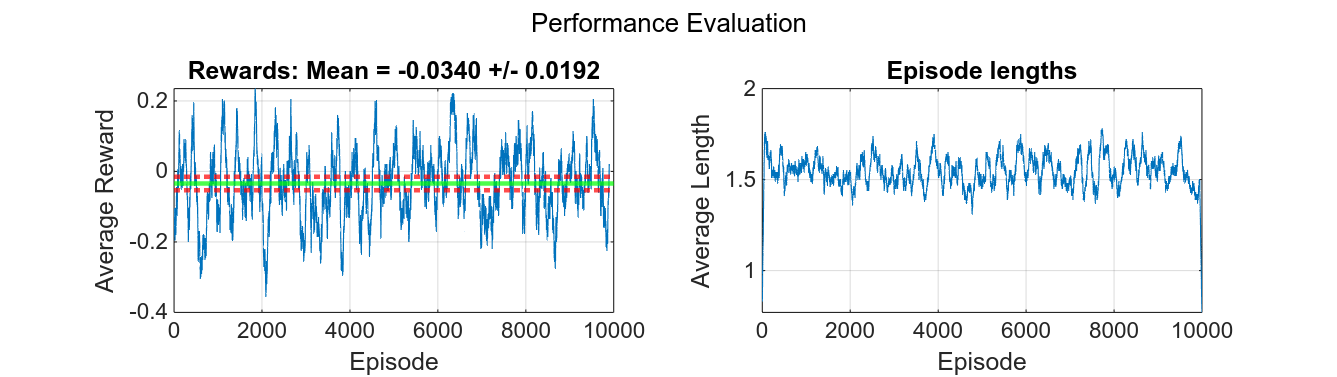

figure;
clf;
% Episode rewards plot
rolling_length = 100;
subplot(1, 2, 1);
reward_moving_average = conv(rewards, ones(rolling_length,1), 'valid') / rolling_length;
plot(1:length(reward_moving_average), reward_moving_average);
title(sprintf('Rewards: Mean = %.4f +/- %.4f', mean_reward, t_value*std_error));
xlabel('Episode');
ylabel('Average Reward');
grid on;
hold on
yline(mean_reward, 'g-', 'LineWidth',2)
yline([ci_lower, ci_upper], 'r:', 'LineWidth',2)
% Episode lengths plot
subplot(1, 2, 2);
length_data = episode_length;
length_moving_average = conv(length_data, ones(rolling_length,1), 'same') / rolling_length;
plot(1:length(length_moving_average), length_moving_average);
title('Episode lengths');
xlabel('Episode');
ylabel('Average Length');
grid on;

% Adjust layout
sgtitle("Performance Evaluation"); 
set(gcf, 'Color', 'white');  % White background

% Adjust spacing between subplots
set(gcf, 'Units', 'Normalized', 'OuterPosition', [0 0 1 1]);
set(findall(gcf, 'Type', 'Axes'), 'FontSize', 10);